# Algoritmos Numéricos por Computadora

# Tercer parcial - Otoño 2020

Sube tu archivo resultado a Canvas $\to$ Examen Parcial 3 antes de las 10am.

Cada pregunta vale 5 puntos.

#### Los exámenes son trabajos individuales. Está estrictamente prohibido dar o recibir ayuda de cualquier persona. 

#### El artículo 29 del Reglamento de Alumnos establece que "se calificará como no acreditada (N.A.) cualquier materia cuando el alumno incurra en alguna práctica fraudulenta".

1. Una ecuación diferencial ordinaria lineal homogénea de segundo orden con coeficientes constantes se representa como $y^{\prime \prime } +ay^{\prime } +b\;y=0$

1.1 Convierte la ecuación anterior  a un sistema de dos ecuaciones de primer orden

1.2 Expresa el sistema de dos ecuaciones de forma vectorial usando una matriz M

1.3 Demuestra que los valores propios $\lambda$ de M satisfacen $\lambda^2 +a\lambda +b=0$

Pega tu respuesta aquí.

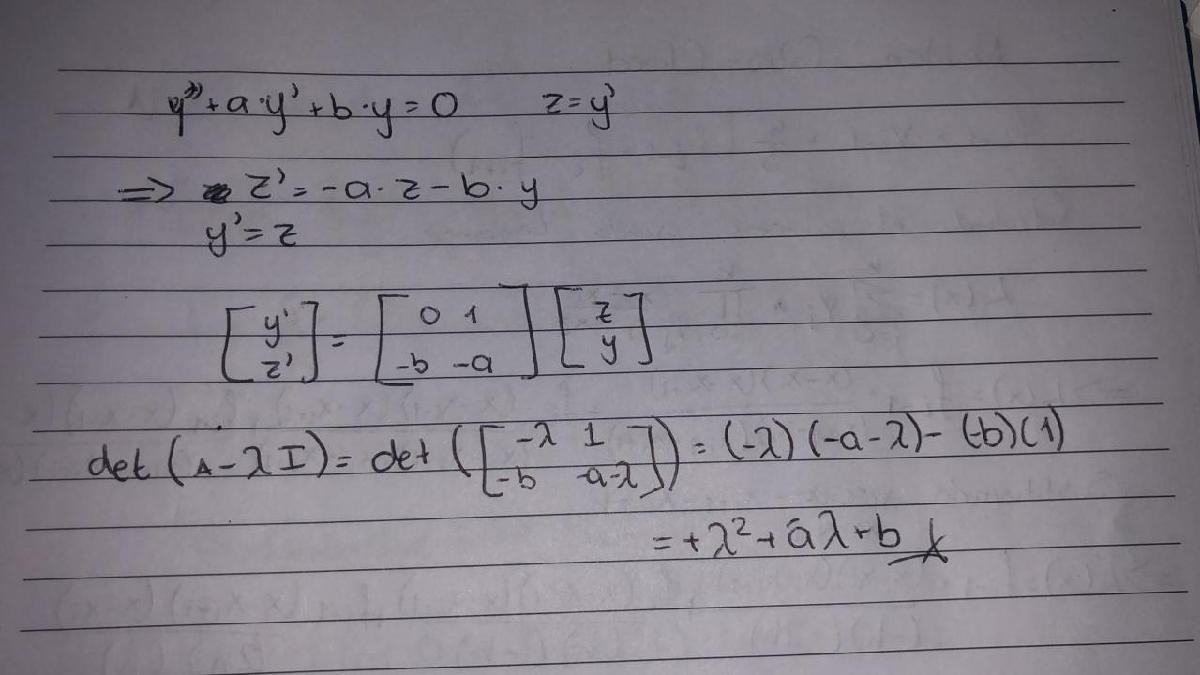

2. Método de Newton-Cotes cerrado.

Dados $f\left(x_{i-1} \right),f\left(x_i \right),f\left(x_{i+1} \right)$ con $x_{i+1} =x_i +h=x_{i-1} +2h$

2.1 Encuentra el polinomio de interpolación de grado 2 que pasa por los tres puntos.

2.2 Integra este polinomio desde $x_{i-1}$hasta $x_{i+1}$ 

2.3 Verifica que la integral es igual a $\frac{h}{3}\left(f\left(x_{i-1} \right)+4f\left(x_i \right)+f\left(x_{i+1} \right)\right)$

Pega tu respuesta aquí.

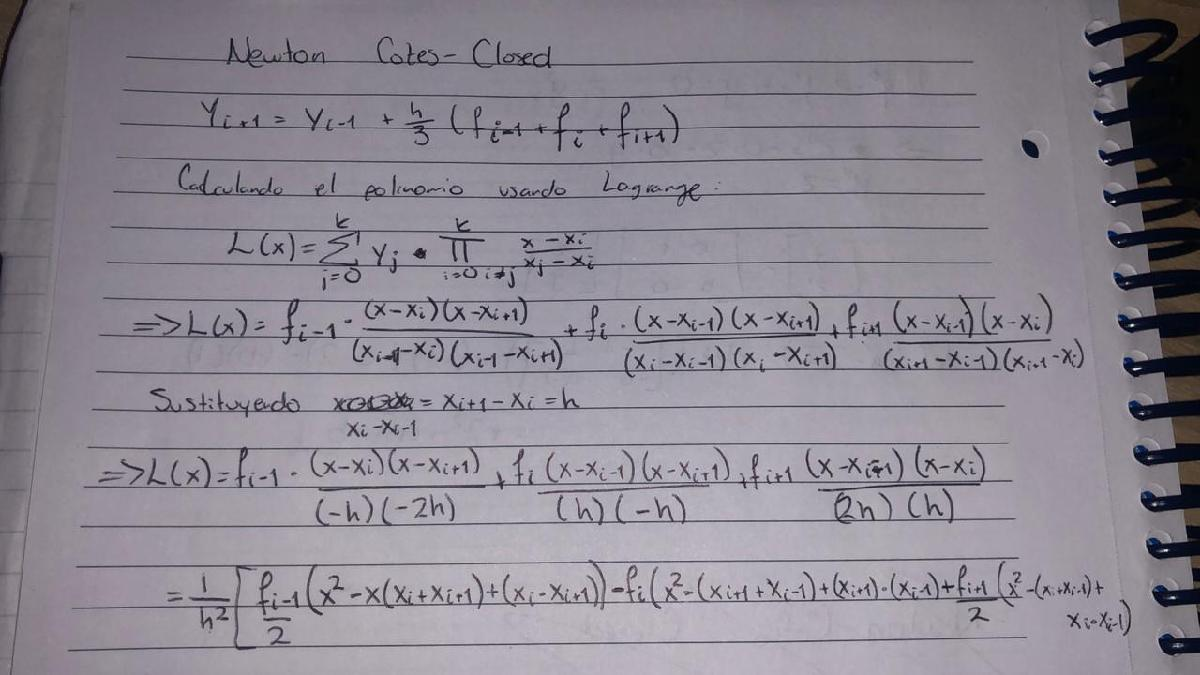

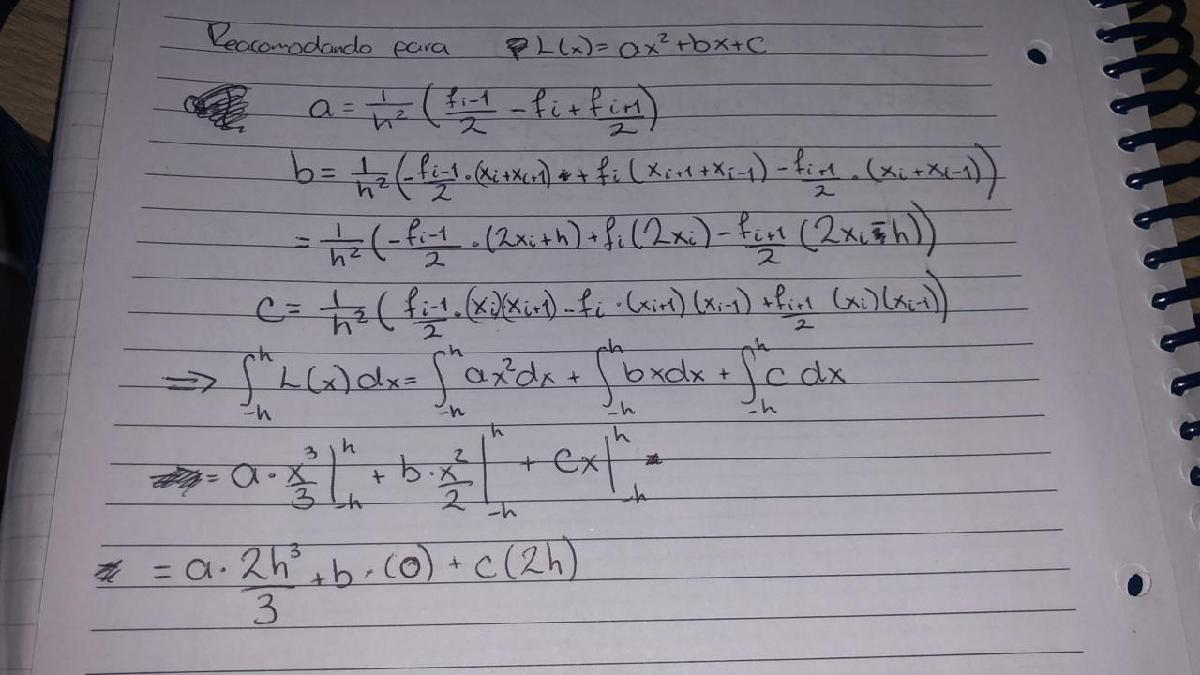

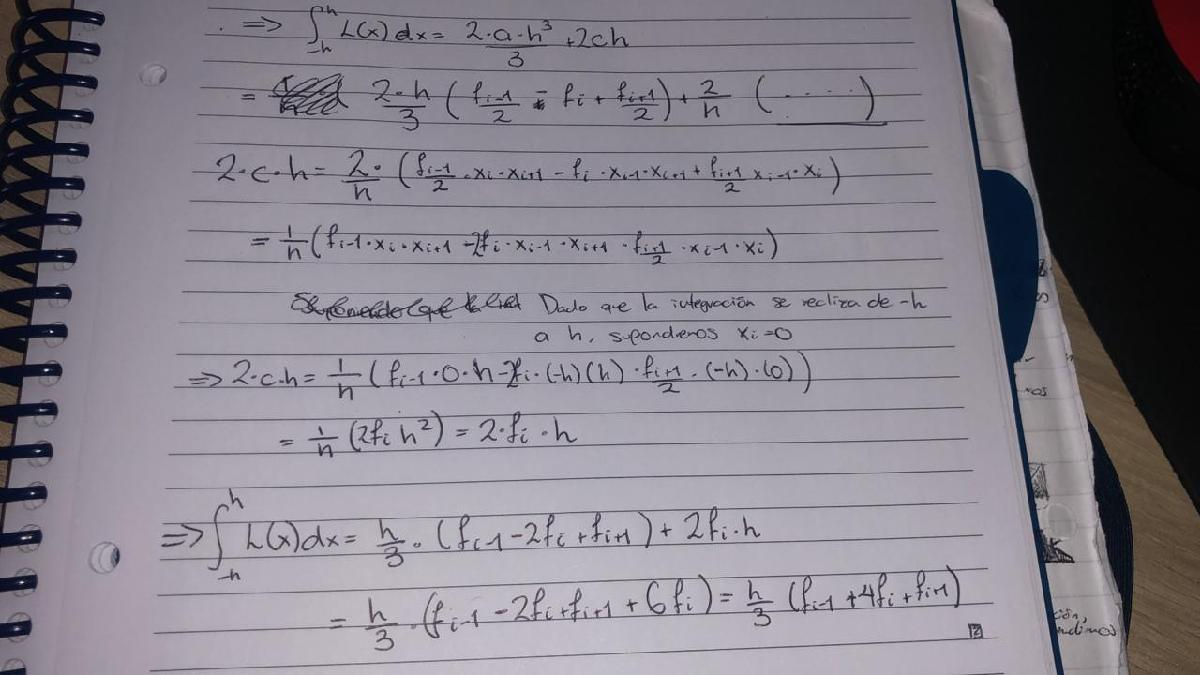

3. Supón que un proyectil se lanza hacia arriba desde la superficie de la Tierra. Se acepta que la única fuerza que actúa sobre el objeto es la fuerza de la gravedad, hacia abajo. En estas condiciones, se usa un balance de fuerza para obtener,


$$v^{\prime } =-g\frac{R^2 }{{\left(R+y\right)}^2 }$$


donde v = velocidad hacia arriba (m/s), t = tiempo (s), y = altitud (m) medida hacia arriba a partir de la superficie terrestre, g =aceleración gravitacional a la superficie terrestre (≈9.81 m/$s^2$), y R = radio de la tierra (≈6.37 × ${10}^6$ m). 

3.1 Encuentra el sistema de dos ecuaciones de primer orden que representa el movimento del proyectil.

% Como la derivada de la velocidad es la aceleración, buscamos una ecuación
% que sea la derivada del movimiento. Esta ecuación sería y'=v
g=9.81;
R=6.37E6;
f=@(t,y) [y(2);-g*R^2/((R+y(1)).^2)];

3.2 Determina, usando rk4 y con un error menor a 0.05s, el tiempo en el que el proyectil alcanza su altura máxima si v(t = 0) = 1 400 m/s.

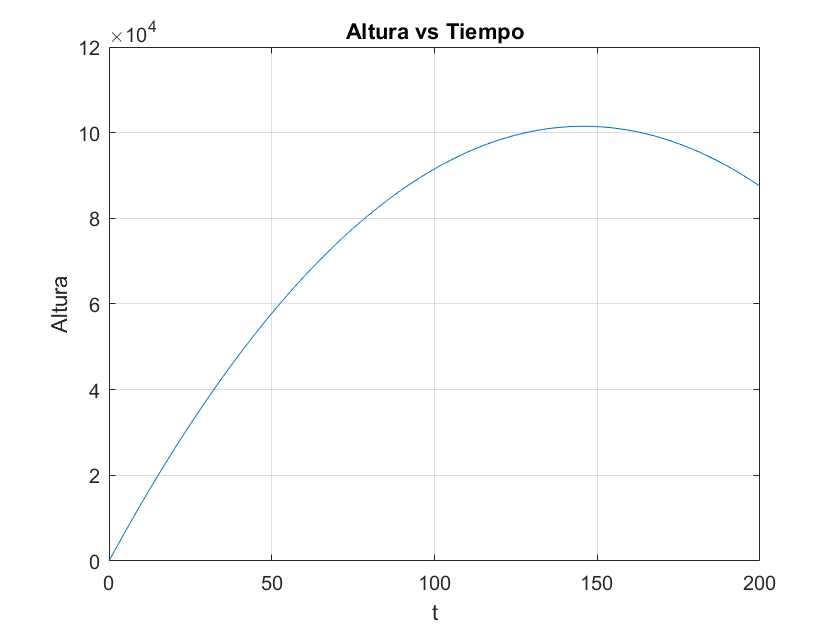

%
y0=[0;1400];
h=0.05;
[t,y] = ivpsV(f, y0, 0, 200, h, 'rk4');
plot(t,y(1,:));
xlabel('t');
ylabel('Altura');
title('Altura vs Tiempo');
grid on;

[yMax,iMax]=max(y(1,:));
tMax=t(iMax)

tMax = 145.7500

3.3 ¿Cuál es la altura máxima (en m) que alcanza el proyectil?

% 
yMax

yMax = 1.0149e+05

4. Las ecuaciones Lokta-Volterra son un par de ecuaciones diferenciales no lineales de primer orden que se usan frecuentemente para describir la dinámica de sistemas biológicos en los que dos especies interactuan, una como presa y otra como depredadora.

Las poblaciones cambian a través del tiempo de acuerdo a las ecuaciones:

$x^{\prime } =\textrm{alfa}*x\;-\;\textrm{beta}*x*y$             presa

$y^{\prime } =\textrm{delta}*x*y\;-\;\textrm{gama}*y$         depredador

4.1 Determina, usando RK4, y grafica cómo evolucionan las poblaciones$x$ y$y$ en función del tiempo si:

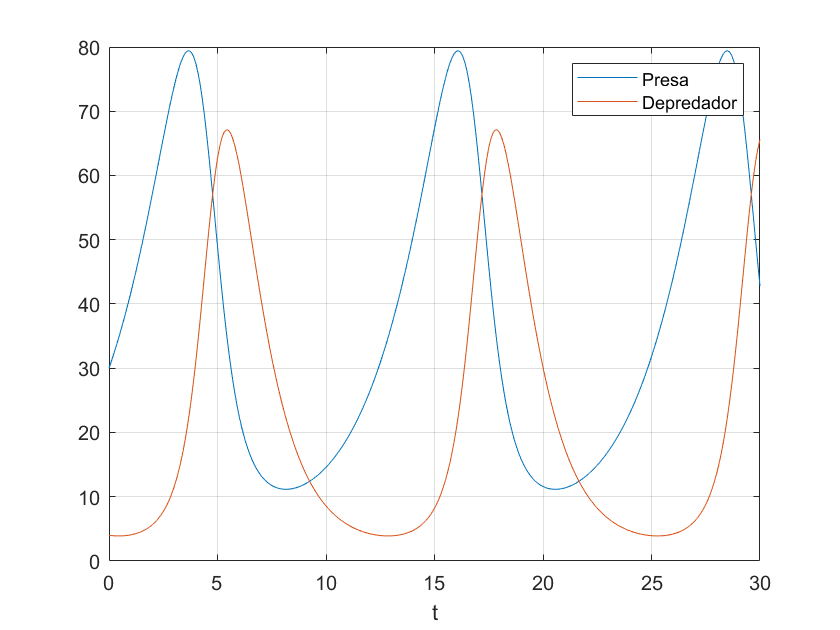

alfa = 0.4;
beta = 0.018;
delta = 0.023;
gama = 0.8;
x0 = 30;
y0 = 4;
tf = 30;
h = 0.1;
f = @(t,y) [alfa*y(1)-beta*y(2)*y(1);delta*y(1)*y(2)-gama*y(2)];
[t,y] = ivpsV(f, [x0;y0], 0, tf, h, 'rk4');
plot(t,y(1,:));
xlabel('t');
hold on;
grid on;
plot(t,y(2,:));
legend('Presa','Depredador');
hold off;

4.2 Grafica $x$ vs.$y$ (phase-plane plot)

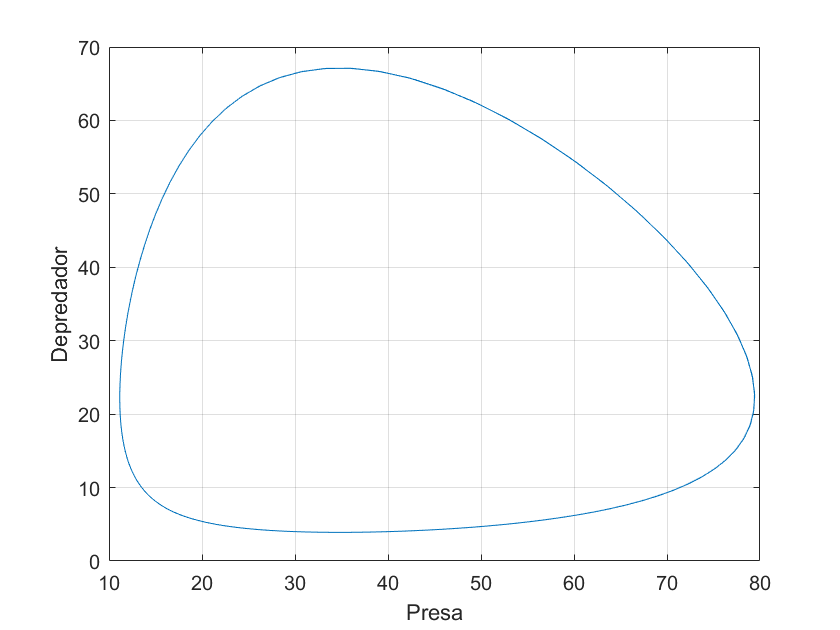

%
plot(y(1,:),y(2,:));
xlabel('Presa');
ylabel('Depredador');
grid on;
hold off;

4.3 Interpreta el funcionamiento del sistema en términos "biológicos"

%La población de las presas crece a una velocidad exponencial al igual que
%la de los depredadores. Como es de esperar, cuando la población de
%depredadores comienza a crecer, empiezan a matar a la población de las
%presas, entonces la de las presas comienza a disminuir. Cuando ya no hay
%presas que comer, la población de los depredadores comienza a bajar, y
%cuando no hay depredadores las presas se reproducen de nuevo a una
%velocidad exponencial.

4.4 Resuelve el mismo sistema usando el método de Euler y dibuja la gráfica phase-plane.

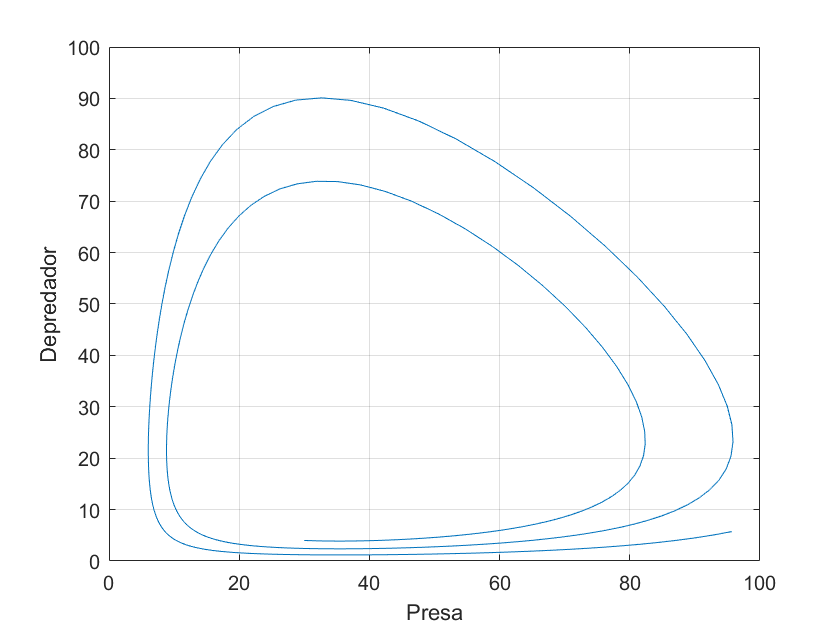

%
[t,y] = ivpsV(f, [x0;y0], 0, tf, h, 'euler');
plot(y(1,:),y(2,:));
xlabel('Presa');
ylabel('Depredador');
grid on;
hold off;

4.5 ¿Por qué no se cierra la figura? ¿Puedes hacer que cierre?

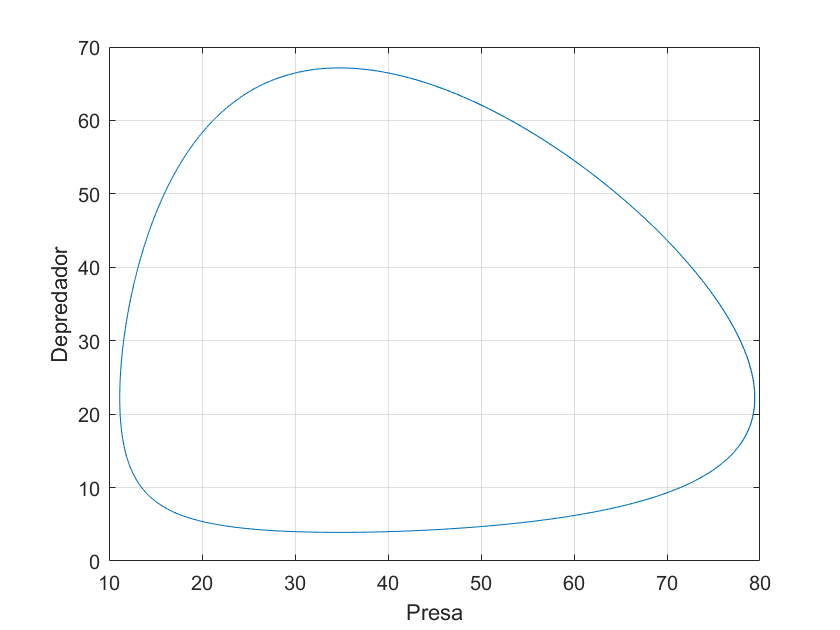

% Porque la RK4 es mucho más exacta que Euler, para hacer que cierre
% necesitariamos una h mucho más pequeña, como ejemplo usaré 0.0001
[t,y] = ivpsV(f, [x0;y0], 0, tf, 0.0001, 'euler');
plot(y(1,:),y(2,:));
xlabel('Presa');
ylabel('Depredador');
grid on;
hold off;

5. Considera el problema de valor inicial

$y^{\prime } =t\;y+t^3$         $y\left(0\right)=1$          t in [0,1]

5.1 Resuelve el problema utilizando los métodos de RK4 y RK45Fehlberg (con una tolerancia relativa de${10}^{-6}$. Grafica las dos soluciones juntas. 

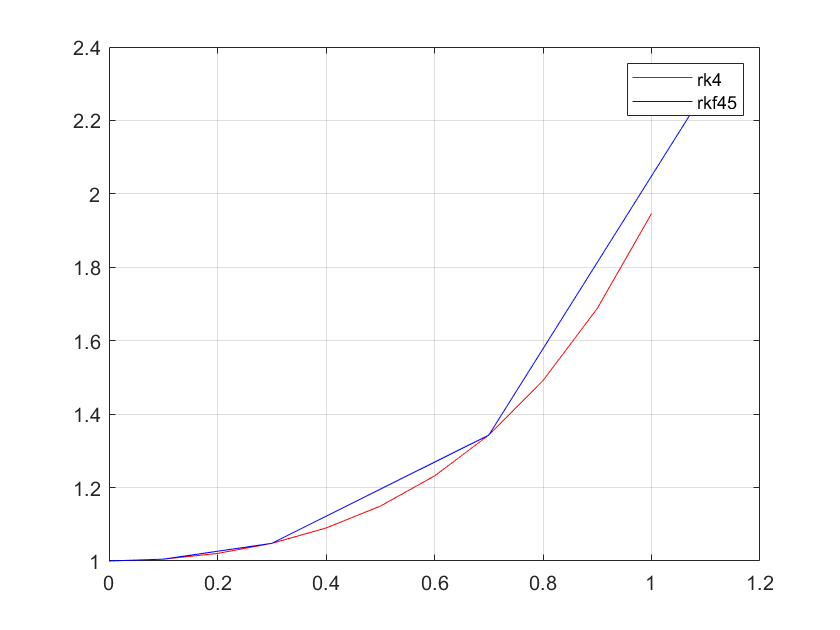

%
f =  @(t,y) t*y+t^3;
y0 = 1;
t0=0;
tf=1;
h = 0.1;
relTol = 10E-6;
max1 = 400;
[t1,y1]= ivpsV(f, y0, 0, tf, h, 'rk4');
[t2,y2] = rkf45(f, y0, t0, tf, h, relTol, max1);
plot(t1,y1, 'r');
hold on;
grid on;
plot(t2,y2,'b');
legend('rk4','rkf45');
hold off;

5.2 ¿Cuántos puntos calcula cada método?

%
puntosRK4=length(t1)

puntosRK4 = 11

puntosRKF45=length(t2)

puntosRKF45 = 5

5.3 ¿Qué metodo crees que es mejor?

% Depende del problema, para sistemas de ecuaciones que tengan cambios
% repentinos, rkf45 ayuda a resolver el sistema. Sin embargo, para
% ejercicios sin cambios abruptos, podría ser más sencillo resolverlo con
% un RK4, que como hemos observado tiene una respuesta efectiva.

6. Si enciendes un cerillo, la esfera de flama crece rápidamente hasta que alcanza un tamaño crítico y mantiene este tamaño porque la cantidad de oxígeno consumido por la combustión en el interior de la esfera equilibra la cantidad disponible sobre la superficie.

Si la variable y(t) representa el radio de la esfera, entonces. 


$$y^{\prime } =y^2 -y^3$$


Los términos $y^2$ y $y^3$ surgen de la superficie y del volumen de la esfera. El parámetro crítico es el radio inicia delta, que es "pequeño".

6.1 Grafica la solución de la ecuación sobre un intervalo de tiempo inversamente proporcional a delta. Utiliza los métodos de Euler y Euler implícito. 

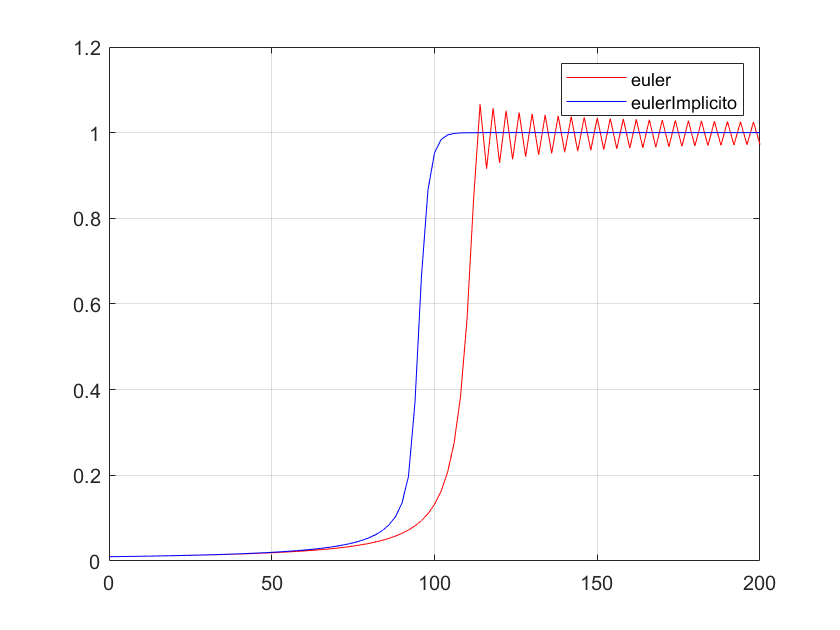

delta = 0.01;
t0 = 0;
tf = 2/delta;
h = (tf-t0)/100;
y0=delta;
f =  @(t,y) y^2-y^3;
[t1,y1]= ivpsV(f, y0, 0, tf, h, 'euler');

[t2,y2] = ImplicitEuler(f, y0, t0, tf, h);

plot(t1,y1, 'r');
grid on;
hold on;
plot(t2,y2,'b');
legend('euler','eulerImplicito');
hold off;

6.2 ¿Qué observas al comparar la solución gráfica obtenida por ambos métodos?

%El cambio en este sistema es muy rápido y despues vuelve a ser lento. La
%aproximación por Euler no es suficiente, debemos usar una h más pequeña
%para lograr un mejor resultado. Por otro lado, como el metodo implicito de
%euler usa cálculos futuros para mejorar los actuales, permite que la
%aproximación se haga más certera.

function [x,y] = ivpsV( f, y0, x0, xf, h, method)
    x= x0:h:xf;
    n=length(x);
    m = length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    
    for i=1:1:n-1
        switch method
        case 'euler'
            phi=f(x(i),y(:,i));
            y(:,i+1)=y(:,i)+phi*h;
        case 'midpoint'
            ymid=y(i)+f(x(i),y(:,i))*h/2;
            phi=f(x(i)+h/2,ymid);
            y(:,i+1)=y(:,i)+phi*h;
        case 'heun'
            s1=f(x(i),y(:,i));
            predictor=y(:,i)+s1*h;
            s2= f(x(i+1), predictor);
            phi = (s1+s2)/2;
            y(:,i+1)=y(:,i)+phi*h;
        case 'rk4'
            k1=f(x(i),y(:,i));
            k2=f(x(i)+h/2,y(:,i)+k1*h/2);
            k3=f(x(i)+h/2,y(:,i)+k2*h/2);
            k4=f(x(i)+h, y(:,i)+k3*h);
            y(:,i+1)=y(:,i)+(k1+2*k2+2*k3+k4)*h/6;
            
        end
    end
end
function [t,y] = rkf45(f,y0,t0,tf,h,relTol,max1)
    t(1) = t0;
    y(:,1) = y0;
    tk = 0;
    
    i = 1;
    cond = true;
    while cond
        wi = y(:,i);
        ti = t(i);
        s1 = f(ti,wi);
        s2 = f(ti+(h/4),wi+(h/4*s1));
        s3 = f(ti+(3/8)*h,wi+(3/32)*h*s1+(9/32)*h*s2);
        s4 = f(ti+(12/13)*h,wi+(1931/2197)*h*s1 - (7200/2197)*h*s2 + (7296/2197)*h*s3);
        s5 = f(ti+h,wi+(439/216)*h*s1-8*h*s2+(3680/513)*h*s3-(845/4104)*h*s4);
        s6 = f(ti+h/2,wi-(8/27)*h*s1+2*h*s2 - (3544/2565)*h*s3 + (1859/4104)*h*s4 - (11/40)*h*s5);
        win = wi + h*((25/216)*s1+(1408/2565)*s3+(2197/4104)*s4-(1/5)*s5);
        zin = wi + h*((16/135)*s1 + (6656/12825)*s3 + (28561/56430)*s4 - (9/50)*s5 + (2/55)*s6);
     
        if norm((zin-win)./zin)>relTol
            h = h/2;
        else
            y(:,i+1) = zin;
            t(i+1) = ti+h;
            tk = t(i+1);
            h = h*2;
            i = i+1;
        end
        
        cond = tk<tf && i<max1;
        
    end
end
function [t,y] = ImplicitEuler(f,y0,t0,tf,h)
    t = t0:h:tf;
    n = length(t);
    m = length(y0);
    y = zeros(m,n);
    y(:,1) = y0;
    
    for i=1:n-1
      k = @(yn) yn - y(:,i) - f(t(i+1),yn)*h;  
      [yi,~] = newRap(k,y(:,i));
      y(:,i+1) = yi;
    end
    
end

function [x,i]=newRap(f,xi)
    fsym=sym(f);
    dfs=diff(fsym);
    df=matlabFunction(dfs);
    xp=xi;
    i=0;
    x=xp-f(xp)/df(xp);
    MAX=1000;
    if dfs==0 && f(x)~=0, error('La derivada de la función es 0, raíces son imaginarias'), end
    while abs((x-xp)/x)>eps && f(x)~=0 && i<MAX
        xp=x;
        x=xp-f(xp)/df(xp);
        i=i+1;
    end
end